Task 1

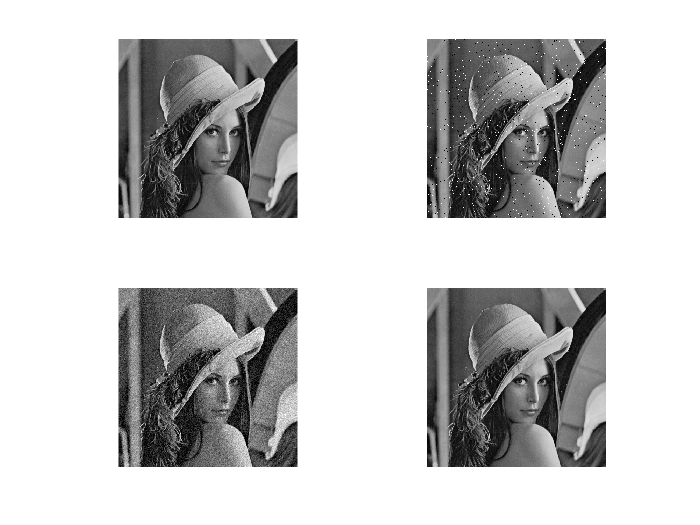

I=imread("lena.jpg");
%figure()
%imshow(I)

J = imnoise(I,'salt & pepper',0.02);
%J = imnoise(I,'salt & pepper');
%figure()
%imshow(J)

K=imnoise(I,'gaussian',0,0.005);
%K=imnoise(I,'gaussian');
%figure()
%imshow(K)

b=0.02;
noise = sqrt(-b*log((1-rand(size(I,1),size(I,2)))));
L=I+uint8(noise);
%figure()
%imshow(L)



figure()
subplot(2,2,1), imshow(I)
subplot(2,2,2), imshow(J)
subplot(2,2,3), imshow(K)
subplot(2,2,4), imshow(L)

Task 2

m=5;n=5;

changedJ=double(J);
changedK=double(K);
changedL=double(L);

disp("Salt and Pepper");

Salt and Pepper


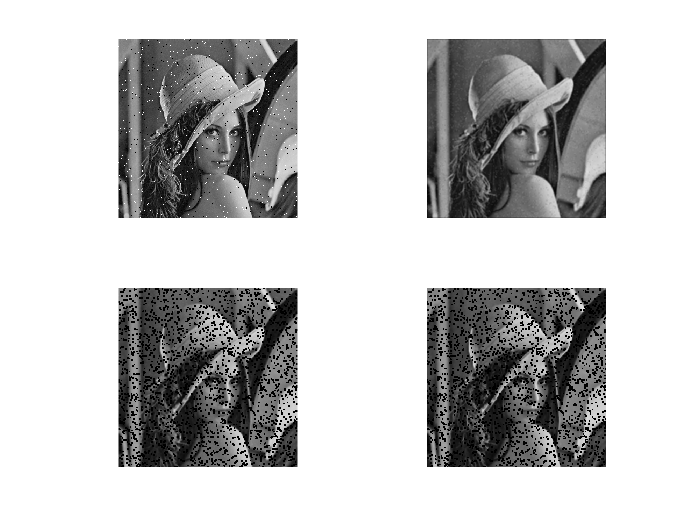

figure()
subplot(2,2,1), imshow(J)
subplot(2,2,2), imshow(uint8(imfilter(changedJ,fspecial('average',[m n]))))
subplot(2,2,3), imshow(uint8(exp(imfilter(log(changedJ),ones(m,n),'replicate')).^(1/(m*n))))
subplot(2,2,4), imshow(uint8((m*n) ./ imfilter(1 ./ (changedJ + eps), ones(m, n), 'replicate')))


disp("Gaussian");

Gaussian


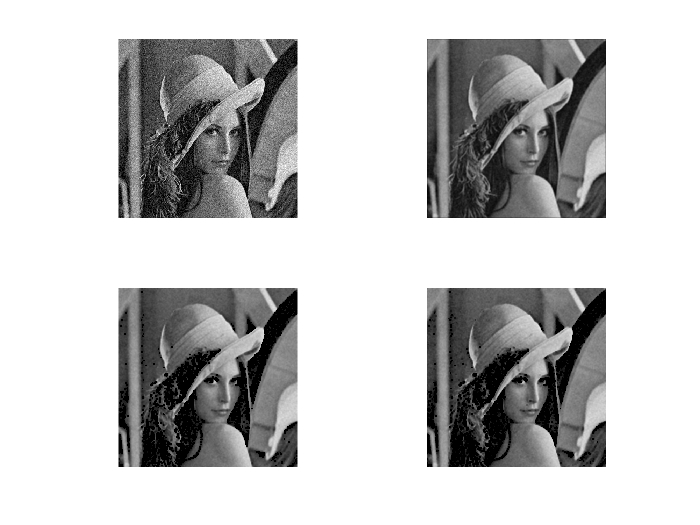

figure()
subplot(2,2,1), imshow(K)
subplot(2,2,2), imshow(uint8(imfilter(changedK,fspecial('average',[m n]))))
subplot(2,2,3), imshow(uint8(exp(imfilter(log(changedK),ones(m,n),'replicate')).^(1/(m*n))))
subplot(2,2,4), imshow(uint8((m*n) ./ imfilter(1 ./ (changedK + eps), ones(m, n), 'replicate')))


disp("Relaigh");

Relaigh


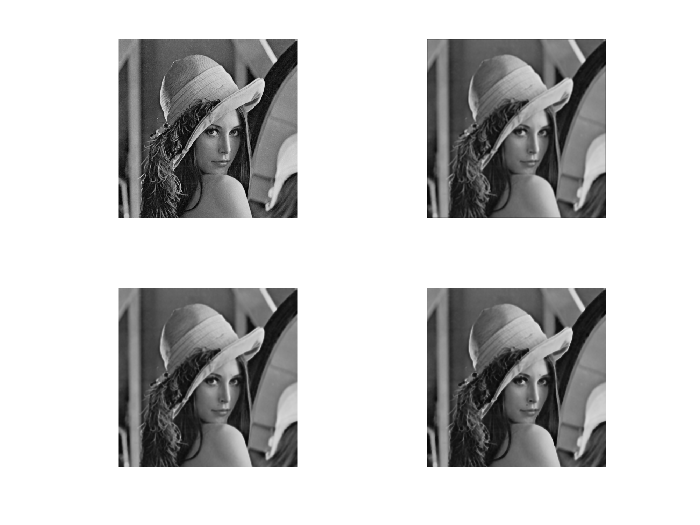

figure()
subplot(2,2,1), imshow(L)
subplot(2,2,2), imshow(uint8(imfilter(changedL,fspecial('average',[m n]))))
subplot(2,2,3), imshow(uint8(exp(imfilter(log(changedL),ones(m,n),'replicate')).^(1/(m*n))))
subplot(2,2,4), imshow(uint8((m*n) ./ imfilter(1 ./ (changedL + eps), ones(m, n), 'replicate')))


% 
% %Harmonic mean filter
% 
% figure()
% subplot(2,2,1), imshow(L)
% subplot(2,2,2), imshow((m*n) ./ imfilter(1 ./ (J + eps), ones(m, n), 'replicate'))
% subplot(2,2,3), imshow((m*n) ./ imfilter(1 ./ (K + eps), ones(m, n), 'replicate'))
% subplot(2,2,4), imshow((m*n) ./ imfilter(1 ./ (L + eps), ones(m, n), 'replicate'))
% 
% J=single(J);
% ChangedK=single(K);
% L=single(L);
% 
% %Geometric mean filter
% figure()
% subplot(2,2,1), imshow(K)
% subplot(2,2,2), imshow(exp(imfilter(log(J),ones(m,n),'replicate')).^(1/(m*n)))
% subplot(2,2,3), imshow(exp(imfilter(log(ChangedK),ones(m,n),'replicate')).^(1/(m*n)))
% subplot(2,2,4), imshow(exp(imfilter(log(L),ones(m,n),'replicate')).^(1/(m*n)))


For Salt and pepper noise, Arithmatic mean filter is better.

For Gaussian noise, Arithmatic mean filter is better.

For Relaigh noise, Harmonic filter performs better.

Task 3

disp("WMF")

WMF


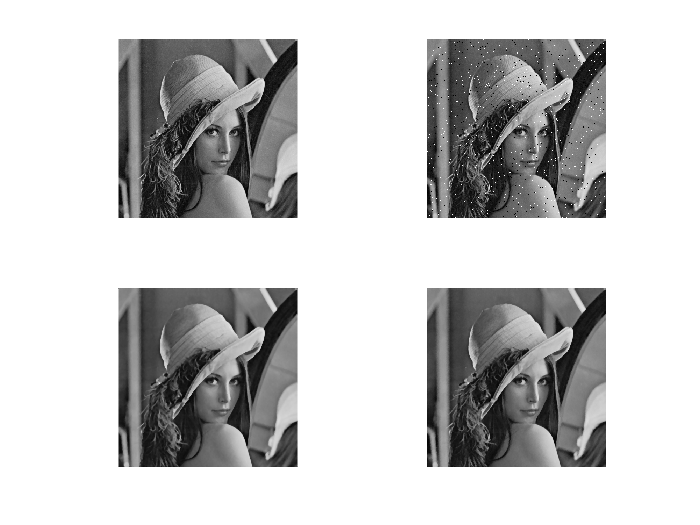


I=imread("lena.jpg");
J = imnoise(I,'salt & pepper',0.02);

filteredImageMedFilter=med_filter(J,5);
filteredImageMedFilter=uint8(filteredImageMedFilter);

filteredImageMedWFilter=med_W_filter(J,5);
filteredImageMedWFilter=uint8(filteredImageMedWFilter);
figure()
subplot(2,2,1), imshow(I)
subplot(2,2,2), imshow(J)
subplot(2,2,3), imshow(filteredImageMedFilter)
subplot(2,2,4), imshow(filteredImageMedWFilter)